# MPC Source code (transfer function models)

This livescript is a brief manual to explain the source code underpinning all the virtual laboratories on an introduction to MPC concepts, tuning and constraint handling. Some of the apps include:

- ***predictionconcepts_control101.mlapp***

- ***mpctuning_control101.mlapp*** 

- ***mpctfilter_control101.mlapp***

- ***mpcfailing_control101.mlapp***.   

Predictions are core to the advanced control technique of model predictive control (MPC) and thus understanding their role and more importantly, how it create them, is essential before engaging with MPC. The code illustrated here is intended to be elementary and easy to follow and thus makes no claim of being robust to misuse. Moreover, again for simplicity, the focus is mainly on SISO transfer function models.

In a similar vein, the code which enables closed-loop simulation with and without uncertainty and also to include constraint handling is deliberately simple in nature because the focus is on illustrating concepts and capability. Of course this has the advantage that the code is transparent in nature and easy to edit for those who wish to.  Users who want more professional/robust code and more complex examples should look into the more extensive MPC toolboxes available.

### Supporting m-files

Users are reminded that if they wish to make any edits to the code listed and used here, please make a copy in you own folder first. A multitude of very similar simulation code examples are provided, but this is deliberate because we provide examples which are the simplest possible context and thus it is easier for users to deconstruct the code. As new concepts are introduced, the code is modified accordingly.     

- mpc_simulate_noconstraints_control101                     The simplest scenario

- mpc_simulate_limited_control101                                Reduces the number of significant figures in core variables.

- mpc_simulate_inputconstraints_control101                 Adds input constraint handling; feasibility guaranteed.

- mpc_simulate_outputconstraints_control101               Adds output constraint handling; feasibility NOT guaranteed.

- mpc_simulate_tfilt_noconstraints_control101              Adds the T-filter for reducing noise sensitivity (no constraints)

- mpc_simulate_tfiltoutputconstraints_control101          Adds the T-filter for reducing noise sensitivity with constraints

- mpc_simulate_noconstraints_withff_control101          Allows the future target information to be used (no constraints)

The simulation files in turn require a number of utility files:

- caha_control101                               Build Toepltiz and Hankel matrices

- mpc_predmat_control101                 Create prediction matrices by iteration of 1 step ahead prediction                

- mpc_predmat_toeplitz_control101    Create prediction matrices from Toepltiz and hankel matrices             

- mpc_predtfilt_control101                   Create prediction matrices linked to T-filter usage

- mpc_constraints2_control101           Build constraint inequalities with input and output constraints

- mpc_constraints_control101             Build constraint inequalities with input constraints

- mpc_law_control101                         Determine the control law parameters (unconstrained)    

For more background on MPC readers can look at the website [https://sites.google.com/sheffield.ac.uk/controleducation/introtompcbook](https://sites.google.com/sheffield.ac.uk/controleducation/introtompcbook) and also a range of popular text books such as that by the author: **A first course in predictive control: 2nd Edition**,  J.A. Rossiter, CRC Press (Taylor and Francis group), 2018, ISBN 9781138099340.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- MPC context

- Forming predictions

- Optimising performance (unconstrained case)

- Simulating the MPC law

- Adding a T-filter to improve the handling of uncertainty

- Constraint handling with GPC - input and output limits

- Using feedforward information from the target

- Appendix: Useful MATLAB functions and case studies

## 1. MPC context

MPC is a control strategy which bases the choice of control input u(k) on the expected system output behaviour y(k), that is the system predictions. In essence, at each sampling instant:

- Postulate a possible future sequence of inputs u(k), u(k+1), ... .

- Evaluate the corresponding future outputs y(k+1|k), y(k+2|k),... .

- Assign some performance measure J(k) to the input/output prediction pair.

- Through some appropriate search over a range of possible future input sequences, determine the one which gives the best expected performance and use the first element of this sequence, that is u(k).

This manual goes through these steps concisely and also introduces an app designed to help students understand these and the basics of MPC design.

**NOTE**: Notation x(k+n|k) means the prediction n-steps ahead, that is a future sample k+n, made at sample k.

For simplicitly this resource focuses on linear SISO models, although the same principles can be used for non-linear and MIMO models, albeit the coding is somewhat more challenging. For this resource we will assume a model of the following form.

$\begin{array}{l}
a\left(z\right)y\left(z\right)=b\left(z\right)u\left(z\right)+d;\;\;\\
y\left(k+1\right)=b_1 u\left(k\right)+\cdots +b_n u\left(k-n+1\right)-a_1 y\left(k\right)-\cdots -a_n y\left(k-n+1\right)+d
\end{array}$    (1)

## 2. Forming predictions

Without going into details (see references) it can be shown that long range predictions can be formed by iterating the difference equation model (1). These can then be formulated in matrix/vector format as shown here.

$\left\lbrack \begin{array}{c}
y\left(k+1|k\right)\\
y\left(k+2|k\right)\\
\vdots \\
y\left(k+n|k\right)
\end{array}\right\rbrack =H\left\lbrack \begin{array}{c}
\Delta u\left(k|k\right)\\
\Delta u\left(k+1|k\right)\\
\vdots \\
\Delta u\left(k+n-1|k\right)
\end{array}\right\rbrack +P\left\lbrack \begin{array}{c}
\Delta u\left(k-1\right)\\
\Delta u\left(k-2\right)\\
\vdots \\
\Delta u\left(k-m\right)
\end{array}\right\rbrack +Q\left\lbrack \begin{array}{c}
y\left(k\right)\\
y\left(k-1\right)\\
\vdots \\
y\left(k-m\right)
\end{array}\right\rbrack$    (2)

The matrics $H,P,Q$ depend upon the system model. 

**Remark**: Readers will note that the prediction equation (2) uses input increments $\Delta u\left(k\right)=u\left(k\right)-u\left(k-1\right)$. While alternatives exist, this is one popular way of ensuring unbiased prediction in the steady-state.

The files used to form the prediction matrices are demonstrated in the code below. The code assumes that the model has a single delay and does not require that associated 'zero' coefficient to be stored in the b vector.

disp('Prediction matrices')

Prediction matrices


a=[1,-1.5, 0.95]; 
b=[0.1 0.1];
ny=4;
[H,P,Q] = mpc_predmat_toeplitz_control101(a,b,ny)

H =     0.1000         0         0         0
    0.3500    0.1000         0         0
    0.6300    0.3500    0.1000         0
    0.8125    0.6300    0.3500    0.1000


P =     0.1000
    0.2500
    0.3800
    0.4325


Q =     2.5000   -2.4500    0.9500
    3.8000   -5.1750    2.3750
    4.3250   -6.9350    3.6100
    3.8775   -6.9863    4.1087


The file uses a subfunction for creating some Hankel/Toeplitz matrices, for example:

[Ca,Ha]=caha_control101(conv(a,[1 -1]),1,3)

Ca =     1.0000         0         0
   -2.5000    1.0000         0
    2.4500   -2.5000    1.0000


Ha =    -2.5000    2.4500   -0.9500
    2.4500   -0.9500         0
   -0.9500         0         0


[Cb,Hb]=caha_control101(b,1,3) 

Cb =     0.1000         0         0
    0.1000    0.1000         0
         0    0.1000    0.1000


Hb =     0.1000
         0
         0


So, for example, $H=C_a^{-1} C_b ,P={C_a^{-1} H}_b ,\;Q=C_a^{-1} H_a \ldotp$ 

**Remark**: More efficient ways of forming the predictions exist but these are somewhat more complicated to code/present and the computational savings are irrelevant for most simple cases with modern computing.

## 3 Optimising performance (unconstrained case)

The user needs to select the future inputs which will lead to the best predicted behaviour. In order to automate the decision making and ensure better consistency, we need some quantitative measure of best. Within the MPC community it is accepted that 2-norm performance measures have a number advantages over alternatives which make them the preferred option in general (a deeper discussion of this point is not appropriate in an introductory resource). Hence  consider the following measure for future performance:

$J=\sum_{i=1}^{\textrm{ny}} {\left(r-y\left(k+i|k\right)\right)}^2 +\lambda \sum_{i=0}^{\textrm{nu}} \Delta u{\left(k+i|k\right)}^2 ;\;\;\;\;\;\;\;\;\Delta u\left(k\right)=u\left(k\right)-u\left(k-1\right)$      (3)

The parameters ny, nu and $\lambda$ are choices: over what horizon do you wish to assess the output predictions, how many changes to the input value will you be making in the predictions and how much do you weight input changes compared to prediction errors. In simple terms the MPC control law reduces to choosing, at every sample, the set of future input increments which minimises J.

Substituting the predictions from equation (2) into the performance index of (3) gives the following.

$E=\left\lbrack \begin{array}{c}
r\left(k+1\right)\\
r\left(k+2\right)\\
\vdots \\
r\left(k+\textrm{ny}\right)
\end{array}\right\rbrack -H\left\lbrack \begin{array}{c}
\Delta u\left(k|k\right)\\
\Delta u\left(k+1|k\right)\\
\vdots \\
\Delta u\left(k+\textrm{nu}-1|k\right)
\end{array}\right\rbrack -P\left\lbrack \begin{array}{c}
\Delta u\left(k-1\right)\\
\Delta u\left(k-2\right)\\
\vdots \\
\Delta u\left(k-m\right)
\end{array}\right\rbrack -Q\left\lbrack \begin{array}{c}
y\left(k\right)\\
y\left(k-1\right)\\
\vdots \\
y\left(k-m\right)
\end{array}\right\rbrack ;\;\;U=\left\lbrack \begin{array}{c}
\Delta u\left(k|k\right)\\
\Delta u\left(k+1|k\right)\\
\vdots \\
\Delta u\left(k+\textrm{nu}-1|k\right)
\end{array}\right\rbrack$     (4)


$$J=E^T E+{\lambda U}^T U$$


Optimising this with respect to the future control increments gives:

$U={\left(H^T H+\lambda I\right)}^{-1} H^T \left(\left\lbrack \begin{array}{c}
r\left(k+1\right)\\
r\left(k+2\right)\\
\vdots \\
r\left(k+\textrm{ny}\right)
\end{array}\right\rbrack -P\left\lbrack \begin{array}{c}
\Delta u\left(k-1\right)\\
\Delta u\left(k-2\right)\\
\vdots \\
\Delta u\left(k-m\right)
\end{array}\right\rbrack -Q\left\lbrack \begin{array}{c}
y\left(k\right)\\
y\left(k-1\right)\\
\vdots \\
y\left(k-m\right)
\end{array}\right\rbrack \right)=P_r \left\lbrack \begin{array}{c}
r\left(k+1\right)\\
r\left(k+2\right)\\
\vdots \\
r\left(k+\textrm{ny}\right)
\end{array}\right\rbrack -D_k \left\lbrack \begin{array}{c}
\Delta u\left(k-1\right)\\
\Delta u\left(k-2\right)\\
\vdots \\
\Delta u\left(k-m\right)
\end{array}\right\rbrack -N_k \left\lbrack \begin{array}{c}
y\left(k\right)\\
y\left(k-1\right)\\
\vdots \\
y\left(k-m\right)
\end{array}\right\rbrack$  (5)

The core controller parameters can be determined using the following function call (SISO case).

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%   Dufut = Pr*rfut - Dk*Dupast - Nk*ypast 
disp('Control law parameters')

Control law parameters


nu=2;
lambda=1;
[Nk,Dk,Pr] = mpc_law_control101(H,P,Q,nu,lambda,1,1)

Nk =     2.9256   -4.6637    2.4865
    1.3676   -2.4633    1.4263


Dk =     0.2617
    0.1501


Pr =     0.7485
    0.3306


**Remark**: In general it is better to assume that $r\left(k+i\right)=r\left(k+1\right)$as the default feedforward $P_r$ often does not work very well otherwise. See references for more discussion of this.

## 4 Simulating the MPC law

The MPC simulation can now be performed using this control law (5) in a loop. Users can see code illustrations of how to do that within the following two files.

- ***mpc_simulate_limited_control101        ***

- ***mpc_simulate_noconstraints_control101  ***

Both of these files assume no constraint handling and thus are the simplest possible implementations. The former file also limits the number of significant figures within some of the matrices in order to emulate limited precision computing hardware although this is not done in any systematic way as the purpose is to illustrate a concept rather than give a precise analysis of the issue.

The corresponding code is below. Readers will note that it is necesssary to define a number of parameters for the simulation so for code compactness these are created in a separate subfunction (***modelchoice.m***). Users can edit the values in there for their own purposes. The input jitteriness is due to measurement noise.

disp('Closed-loop simulations')

Closed-loop simulations


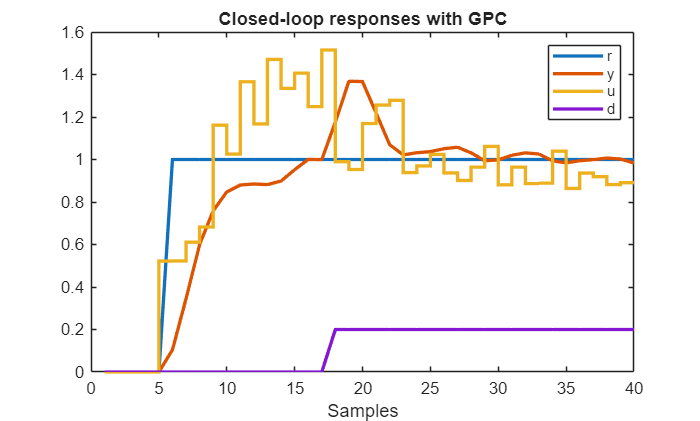


runtime=40;
init=5;  % As MATLAB only allows positive indices, in essence this is to ensure that the simulation has all data needed
ref = [zeros(1,init),ones(1,runtime-init)];  % Assumed target signal
dist=[zeros(1,init+12),ones(1,runtime-init-12)]*0.2; % assumed output disturbance
noise = [zeros(1,init),randn(1,runtime-init)]/50;                % assumed measurement noise

% load simulation data from file
choice =4 ; % Section will run automatically when this is changed
[a,b,ny,nu,lambda,umin,umax,Dumax,ymin,ymax,Tfilt,ap,bp]=modelchoice(3);
            
% simulation - you can choose which code to use
[y,u,Du,r,init] = mpc_simulate_limited_control101(b,a,bp,ap,nu,ny,lambda,1,ref,dist,noise);
%[y,u,Du,r,init] = mpc_simulate_noconstraints_control101(b,a,bp,ap,nu,ny,lambda,1,ref,dist,noise);

% plotting
plotting(r,u,y,dist,runtime)

**Remark**: For simplicity the code in sections 5 and 6 below does not allow for parameter uncertainty, but as will be evident from the files in this section, that would be straightforward to add should the user wish to.

## 5 Adding a T-filter to improve the handling of uncertainty

It was observed very early on by researchers that a GPC type of control law can be very sensitive to measurement noise; in fact prediction using step response or FIR models is less sensitive to measurement noise in general. Similarly it was noted that the control law (5) is not unique in that one can form a Youla parameterisation which gives identical mappings from target to input/output (nominal case), but very different mappings for uncertainty (e.g. noise and disturbances). These notes are not the place to explain the theoretical background to those issues (see references) but rather to highlight them so that learners of MPC gain some awareness.

### 5.1. Theoretical background

The T-filter is a simplified approach to Youla parameterisation whereby one filters the output and input before prediction and then de-filters afterwards before use in the optimisation of prediction performance.

Conceptually, define the filter signals as follows:

$\tilde{y} =\frac{y}{T};\;\tilde{u} =\frac{u}{T}$ where typical the filterning is considered be a low pass type of operation. For sensible sample rates common choices for T are:


$$T={\left(1-0\ldotp 8\right)}^{-n} ,{\;\;\;\left(1-0\ldotp 9\right)}^{-n} \;,n=1,2$$


While there is quite a lot of literature on the topic in the 1990s, more recent work uses state space models and focuses on the state estimation equivalent and thus here we focus on the concepts, not the fine details of actual design. What will be evident from the example below is that a simple T-filter:

- Reduces the sensitivity of the input signal to noise which is essential in practice to avoid excessive chatter on the input.

- Increases the output sensitivity to low frequency output distrurbances.

### 5.2. MATLAB code for MPC with a T-filter

The following code includes a T-filter, but no constraint handling.  It compares the responses with and without a T-filter so that readers can determine for themselves whether this has a core benefit. It is particular noticeable from the figures that the T-filter reduces input sensitivity to measurement noise but conversely, output disturbance rejection is worse.

disp(' ');

disp('Simulations with and without a T-filter; Section 5.2')

Simulations with and without a T-filter)



runtime=40;
init=5;  % As MATLAB only allows positive indices, in essence this is to ensure that the simulation has all data needed
ref = [zeros(1,init),ones(1,runtime-init)];  % Assumed target signal
dist=[zeros(1,init+12),ones(1,runtime-init-12)]*0.2; % assumed output disturbance
noise = [zeros(1,init),randn(1,runtime-init)]/50;                % assumed measurement noise

% load simulation data from file
choice =2 ; % Section will run automatically when this is changed
[a,b,ny,nu,lambda,umin,umax,Dumax,ymin,ymax,Tfilt,ap,bp]=modelchoice(choice);

%  Simulation with noise and no disturbance
[yT,uT,DuT,r] = mpc_simulate_tfilt_noconstraints_control101(b,a,Tfilt,nu,ny,lambda,1,ref,dist*0,noise);
[y,u,Du,r] = mpc_simulate_tfilt_noconstraints_control101(b,a,[1 0],nu,ny,lambda,1,ref,dist*0,noise);
disp('Noise but no disturbance')

Noise but no disturbance


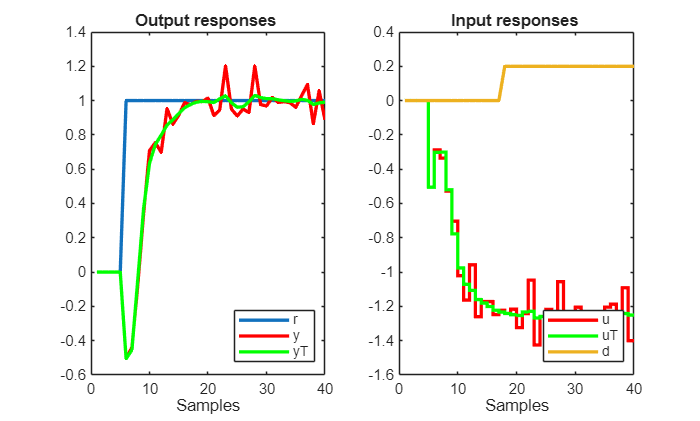

plotting2(r,u,y,uT,yT,dist,runtime)


%  Simulation with no noise and with disturbance
[yT,uT,DuT,r] = mpc_simulate_tfilt_noconstraints_control101(b,a,Tfilt,nu,ny,lambda,1,ref,dist,noise*0);
[y,u,Du,r] = mpc_simulate_tfilt_noconstraints_control101(b,a,[1 0],nu,ny,lambda,1,ref,dist,noise*0);
disp('Disturbance but no noise')

Disturbance but no noise


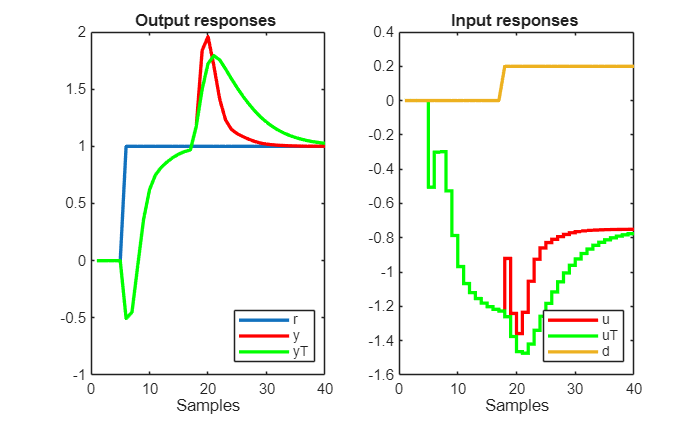

plotting2(r,u,y,uT,yT,dist,runtime)

## 6 Constraint handling with GPC - input and output limits

Real systems have limits, for example a tap can move between 0 and 100% (closed to fully open). Inputs may also have rate limits in that that cannot be changed instantaneously from one value to another. These limits can be expressed in simple inequalities such as:

${\underline{u} <\;u}_k <\bar{u} ;\;\;\underline{\Delta u} <\Delta u_k <\bar{\Delta u} ;\;\;\;k=0,1,2,\cdots$   (6)

State and ouput limits would take a similar format but would need to exploit the prediction equations and thus become dependent on current and past input/ouput data, for example:


$$\left\lbrack \begin{array}{c}
1\\
1\\
\vdots 
\end{array}\right\rbrack \underline{y} \le H\left\lbrack \begin{array}{c}
\Delta u\left(k|k\right)\\
\Delta u\left(k+1|k\right)\\
\vdots \\
\Delta u\left(k+n-1|k\right)
\end{array}\right\rbrack +P\left\lbrack \begin{array}{c}
\Delta u\left(k-1\right)\\
\Delta u\left(k-2\right)\\
\vdots \\
\Delta u\left(k-m\right)
\end{array}\right\rbrack +Q\left\lbrack \begin{array}{c}
y\left(\textrm{kk}\right)\\
y\left(k-1\right)\\
\vdots \\
y\left(k-m\right)
\end{array}\right\rbrack \le \left\lbrack \begin{array}{c}
1\\
1\\
\vdots 
\end{array}\right\rbrack \bar{y}$$


The control law optimisation therefore needs modifying from what was given in section 3 so that constraints are considered within the performance optimisation, that is, we determine the optimal predictions subject to constraints. This is summarised as:


$$\min_U \;J\;s\ldotp t\ldotp \left(6\right)$$


This is what is known as a quadratic programming optimisation (quadratic performance index and linear inequalities). Again it is not the purpose of this summary to derive and explain that in detail, but suffice to say that there are many robust and reliable solvers. MATLAB itself has a solver ***quadprog.m*** within the optimisation toolbox.

**Remark**: There are deliberately multiple alternative choices of the code below because the simpler the code the easier it is to follow for a user who wishes to make edits and modify for their own purposes. The code in the final subsection 6.3 can produce the same results as all the earlier variants, but it is more complicated because it covers several scenarios whereas the code in section 6.1 is somewhat simpler as it covers only the nominal case with input constraints. Indeed the code of section 6.3 can also replicate all the results in section 5 by simply setting the constraints to be very large.

### 6.1. Building the inequalities

In order for the QP to be used, we need to represent any constraints in the following form:


$$M\;U\le f$$


Consequently we need some code to construct the matrix/vector pair $M,f$. The code provided is the following:

- ***mpc_constraints_control101 ***            Forms $M,f$ with only input constraints        

- ***mpc_constraints2_control101***           Forms $M,f$ with only input and output constraints

Criticially the user should note that $M$is fixed (for linear systems) but conversely $f$ is time varying, that is it depends on the current/past state. 

So, with only input constraints: $M\;U\le f_1 +f_2 u\left(k-1\right)$

***    [M,f1,f2]  = mpc_constraints_control101(Dumax,umax,umin,sizeu,nu,H,P,Q);***

With output constraints:  $M\;U\le f_1 +f_2 u\left(k-1\right)+f_3 \left\lbrack \begin{array}{c}
\Delta u\left(k-1\right)\\
\Delta u\left(k-2\right)\\
\vdots 
\end{array}\right\rbrack$$+f_4 \left\lbrack \begin{array}{c}
y\left(k\right)\\
y\left(k-1\right)\\
\vdots 
\end{array}\right\rbrack$

***    [M,f1,f2,f3,f4]  = mpc_constraints2_control101(Dumax,umax,umin,ymax,ymin,sizeu,nu,H,P,Q);***

disp('Section 6:1. Examples of constraint matrices')

Section 6:1. Examples of constraint matrices



% input constraints only
Dumax=0.3; umax=1.2; umin=-0.4; sizeu=1;nu=3;
[M,f,f1]  = mpc_constraints_control101(Dumax,umax,umin,sizeu,nu)

M =      1     0     0
     0     1     0
     0     0     1
    -1     0     0
     0    -1     0
     0     0    -1
     1     0     0
     1     1     0
     1     1     1
    -1     0     0
    -1    -1     0
    -1    -1    -1


f =     0.3000
    0.3000
    0.3000
    0.3000
    0.3000
    0.3000
    1.2000
    1.2000
    1.2000
    0.4000
    0.4000
    0.4000


f1 =      0
     0
     0
     0
     0
     0
    -1
    -1
    -1
     1
     1
     1



% Output constraints
a=[1,-1.5, 0.95]; b=[0.1 0.1];ymin=-0.5;ymax=1.3;
ny=4; nu=2;
[H,P,Q] = mpc_predmat_toeplitz_control101(a,b,ny);
[M,f1,f2,f3,f4]  = mpc_constraints2_control101(Dumax,umax,umin,ymax,ymin,sizeu,nu,H(:,1:nu),P,Q)

M =     1.0000         0
         0    1.0000
   -1.0000         0
         0   -1.0000
    1.0000         0
    1.0000    1.0000
   -1.0000         0
   -1.0000   -1.0000
    0.1000         0
    0.3500    0.1000
    0.6300    0.3500
    0.8125    0.6300
   -0.1000         0
   -0.3500   -0.1000
   -0.6300   -0.3500


f1 =     0.3000
    0.3000
    0.3000
    0.3000
    1.2000
    1.2000
    0.4000
    0.4000
    1.3000
    1.3000
    1.3000
    1.3000
    0.5000
    0.5000
    0.5000


f2 =      0
     0
     0
     0
    -1
    -1
     1
     1
     0
     0
     0
     0
     0
     0
     0


f3 =          0
         0
         0
         0
         0
         0
         0
         0
   -0.1000
   -0.2500
   -0.3800
   -0.4325
    0.1000
    0.2500
    0.3800


f4 =          0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
   -2.5000    2.4500   -0.9500
   -3.8000    5.1750   -2.3750
   -4.3250    6.9350   -3.6100
   -3.8775    6.9863   -4.1087
    2.5000   -2.4500    0.9500
    3.8000   -5.1750    2.3750
    4.3250   -6.9350    3.6100


### 6.2 Code with input limits

This code provides a small number of examples to illustrate constaint handling where the only constraints are on the inputs. The app *********.m **gives the user the ability to modify the limits and horizon choices and thus explore more closely how these impact on behaviour.

disp('Section 6.2: input constraint handling')

Section 6.1: input constraint handling


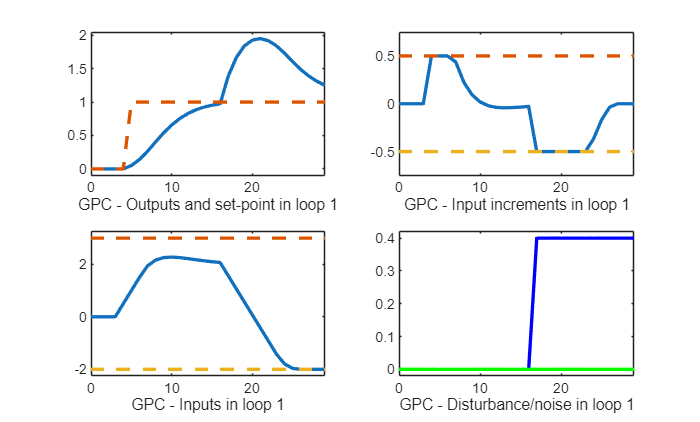


runtime=40;
init=5;  % As MATLAB only allows positive indices, in essence this is to ensure that the simulation has all data needed
ref = [zeros(1,init),ones(1,runtime-init)];  % Assumed target signal
dist=[zeros(1,init+12),ones(1,runtime-init-12)]; % assumed output disturbance
noise = [zeros(1,init),randn(1,runtime-init)]/50;                % assumed measurement noise

choice =1 ; % Section will run automatically when this is changed
[a,b,ny,nu,lambda,umin,umax,Dumax,ymin,ymax]=modelchoice(choice);

dist= dist*0.4;  % Use zero or other magnifier as needed
noise=noise*0;

[y,u,Du,r] = mpc_simulate_inputconstraints_control101(b,a,nu,ny,lambda,1,Dumax,umax,umin,ref,dist,noise);

### 6.2 Output limits and feasibility

With infinite hroizon predictive control algorithms and only input constraints, the QP will always have a solution, that is, the problem is feasible. Howver, when output or state constraints are introduced, there is always the possibility that these constraints may be inconsistent with the input constraints: this scenario is denoted as infeasibility. It is not the purpose of these intoductory resources to explore feasibility in any detail as this is a highly complex area, however, rather it as a warning not to set ouput constraints which are too challenging as the simplistic code given here may simply report: NO ANSWER possible and stop the simulation. 

Code used on real applications needs careful design to have fallback decision making when the default requirements are inconsistent, but such designs are often bespoke rather than generic. Infeasibility can be a problem during inexpected disturbances or fast/large set point changes so I would advise keeping these values small until you have more holistic code which is designed to handled this. For now you will see the code below has set noise and disturbances to be zero.

disp('Section 6.3: output constraint handling')

Section 6.2: output constraint handling


Ignoring output constraints at sample 18
Ignoring output constraints at sample 19
Ignoring output constraints at sample 20
Ignoring output constraints at sample 21
Ignoring output constraints at sample 22


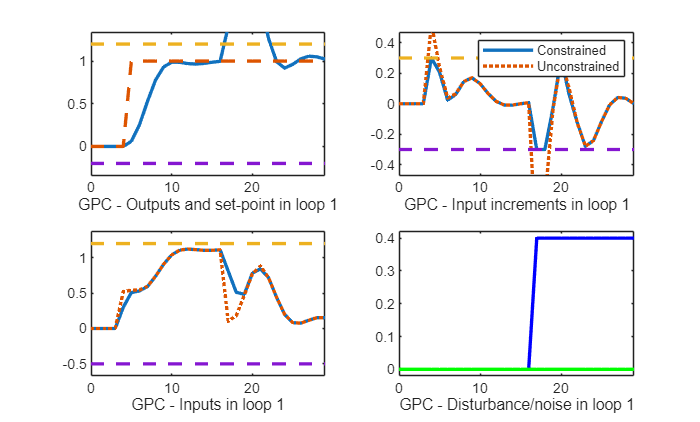


runtime=40;
init=5;  % As MATLAB only allows positive indices, in essence this is to ensure that the simulation has all data needed
ref = [zeros(1,init),ones(1,runtime-init)];  % Assumed target signal
dist=[zeros(1,init+12),ones(1,runtime-init-12)]; % assumed output disturbance
noise = [zeros(1,init),randn(1,runtime-init)]/50;                % assumed measurement noise

choice =3;  % Section will run automatically when this is changed
[a,b,ny,nu,lambda,umin,umax,Dumax,ymin,ymax]=modelchoice(choice);

dist= dist*0.4;  % Use zero or other magnifier as needed
noise=noise*0;

[y,u,Du,r] = mpc_simulate_outputconstraints_control101(b,a,nu,ny,lambda,1,Dumax,umax,umin,ymax,ymin,ref,dist,noise);

### 6.3 Constraint handling with  a T-filter

Constraint handling with a T-filter is much the same as above with the only exception that the coding is slightly more complicated. The insights will largely duplicate what was shown in section 5, although, as the constrained control law is non-linear, there will be some differences as the decision making is constraint driven at times so linear sensitivity analysis will not always be applicable. 

Remember however, that  with no noise or disturbances the responses should be same as with no T-filter.

disp('Section 6.4: constraint handling with T-filter')

Section 6.3: constraint handling with T-filter



runtime=40;
init=5;  % As MATLAB only allows positive indices, in essence this is to ensure that the simulation has all data needed
ref = [zeros(1,init),ones(1,runtime-init)];  % Assumed target signal
dist=[zeros(1,init+12),ones(1,runtime-init-12)]; % assumed output disturbance
noise = [zeros(1,init),randn(1,runtime-init)]/50;                % assumed measurement noise

choice =7  % Section will run automatically when this is changed

choice = 7

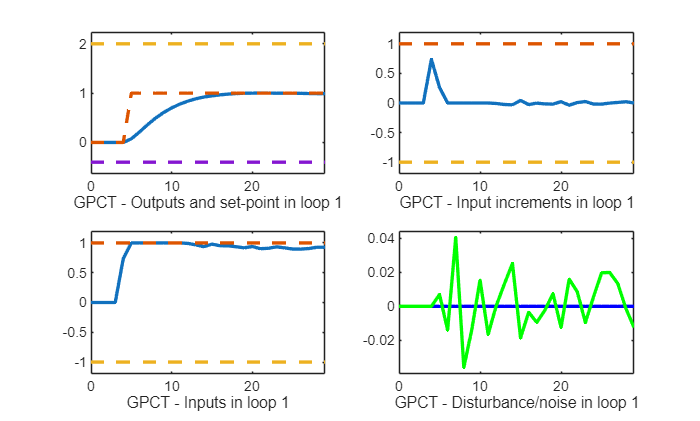

[a,b,ny,nu,lambda,umin,umax,Dumax,ymin,ymax,Tfilt]=modelchoice(choice);

dist=dist*0; % Making zero for now but user can change
noise=noise*1;  

[y,u,Du,r] = mpc_simulate_tfiltoutputconstraints_control101(b,a,Tfilt,nu,ny,lambda,1,Dumax,umax,umin,ymax,ymin,ref,dist,noise);

### 6.4 MIMO examples

The code will also work with square MIMO examples stored as a matrix fraction description, that is:

$A\left(z\right)y=B\left(z\right)u$  where $A\left(z\right),\;B\left(z\right)$ are matrix polynomials. For convenience these are stored in MATLAB using the following format $A=\left\lbrack \textrm{A0},\textrm{A1},\textrm{A2},\cdots \right\rbrack$. A few examples are stored in a subfunction at the end and the indicative code to utilise these is here.

disp('Section 6.5: MIMO examples')

Section 6.4: MIMO examples


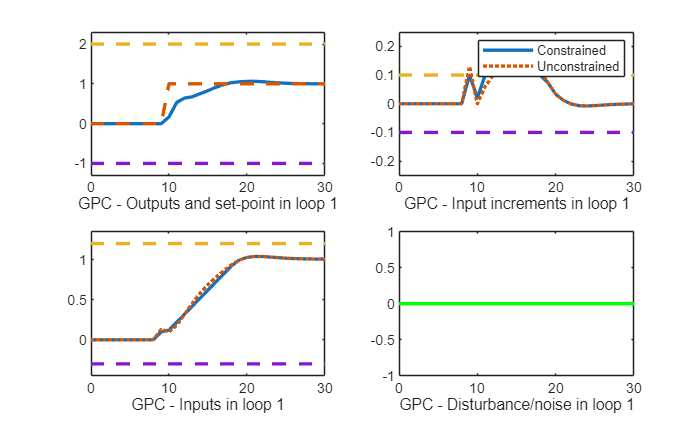

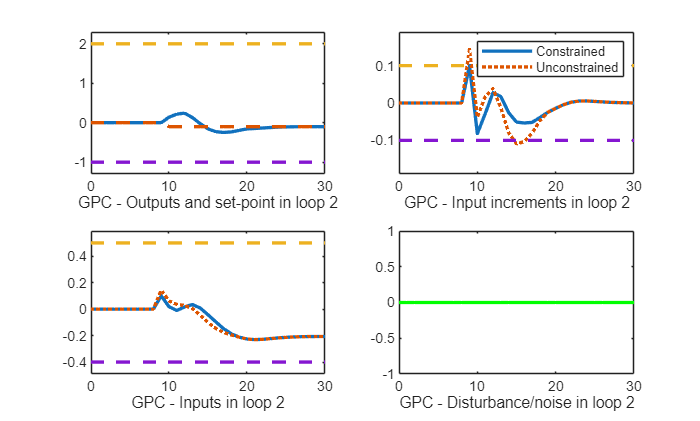

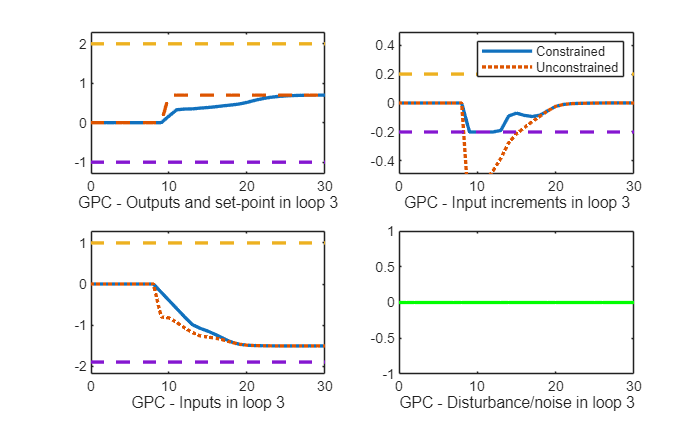


choice=1; % Choose scenario (1 or 2)
[a,b,ny,nu,Wu,Wy,umin,umax,Dumax,ymin,ymax,Tfilt,ref,dist,noise]=modelchoice_mimo(choice);

[y,u,Du,r] = mpc_simulate_outputconstraints_control101(b,a,nu,ny,Wu,Wy,Dumax,umax,umin,ymax,ymin,ref,dist,noise);

## 7 Using feedforward information from the target

One of the purported advantages of MPC was its ability to use information about the future target within the decision making. Of course, while this is true in principle, it is sadly not in reality for typical algorithms. This is because of a mismatch between the assumptions within the optimisation and what actually happens.

The optimisation asks the question, what is the best prediction you can give subject to some tight constraints on the input structure such as, it must be fixed after nu samples? That constraint is artificial and particularly unhelpful if any changes in the references occur more than nu samples into the future. In essence we are asking the planning to use control moves now to deal with target changes in the future and this misalignment in timing will inevitably lead to undesirable compromises. The example code and figure below illustrates the issue as long as na>>nu; it can be seen that the input begins moving too much too soon (that is unnecessarily) before the target change.

Trying experimenting with different values of na to explore the issue.

disp('Section 7 on feedforward information')

Section 7 on feedforward information


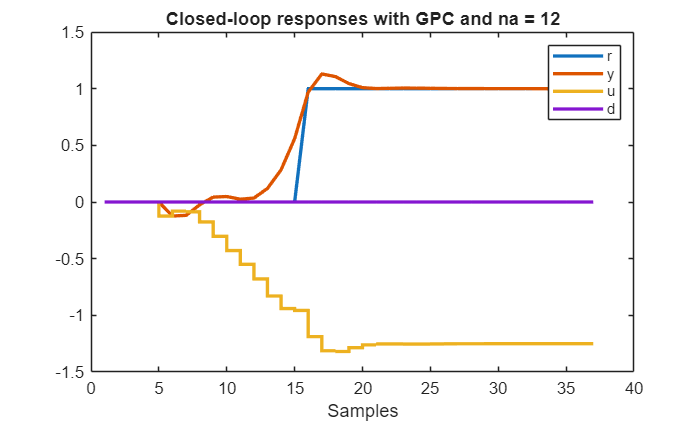

runtime=50;
init=15;  % As MATLAB only allows positive indices, in essence this is to ensure that the simulation has all data needed
ref = [zeros(1,init),ones(1,runtime-init)];  % Assumed target signal
dist=[zeros(1,init+12),ones(1,runtime-init-12)]; % assumed output disturbance
noise = [zeros(1,init),randn(1,runtime-init)]/50;                % assumed measurement noise

choice =2;  % Section will run automatically when this is changed
[a,b,ny,nu,lambda]=modelchoice(choice);

dist=dist*0; % Making zero for now but user can change
noise=noise*0;  

na=12;  % This is the number of future reference values to be used. CAPPED at ny
if na>ny;na=ny;end

[y,u,Du,r] = mpc_simulate_noconstraints_withff_control101(b,a,nu,ny,lambda,1,ref,dist,noise,na);

plotting(r,u,y,dist,length(y))
title(['Closed-loop responses with GPC and na = ',num2str(na)])

**Remark**: This area is not much studied and general guidance is to keep na small, na being the number of future reference values used within the optimisation. To avoid confusing concepts and issues, the code is only supplied for the constraint free and nominal case; any insights would apply to more general scenarios.

## Appendix: Useful MATLAB functions and case studies

### Plotting of basic signals

% Simple plot of all relevant signals
function plotting(r,u,y,d,runtime)

tt=1:runtime;
clf
plot(tt,r(tt),tt,y(tt),'LineWidth',2);
hold on
stairs(tt,u(tt),'LineWidth',2)
plot(tt,d(tt),'LineWidth',2)
legend('r','y','u','d')
xlabel('Samples')
title('Closed-loop responses with GPC')
end


### Plotting of basic signals overlaid with those from a T-filter approach

% Simple overlaying plot of all relevant signals with a T filter
function plotting2(r,u,y,uT,yT,dist,runtime)

clf
tt=1:runtime;
subplot(121)
aa=plot(tt,r(tt),tt,y(tt),'r-',tt,yT(tt),'g-','LineWidth',2);
legend('r','y','yT','Location','southeast')
title('Output responses ')
xlabel('Samples')

subplot(122)
stairs(tt,u(tt),'r-', 'LineWidth',2); hold on
stairs(tt,uT(tt),'g-','LineWidth',2); 
plot(tt,dist(tt),'LineWidth',2)
legend('u','uT','d','Location','southeast')

xlabel('Samples')
title('Input responses ')
end


### Model definitions for simulation studies (SISO)

%%%%% CASE STUDIES

    % Define multiple different siso scenarios
function [a,b,ny,nu,lambda,umin,umax,Dumax,ymin,ymax,Tfilt,ap,bp]=modelchoice(n)


switch n
    case 1
        a=[1 -0.8];b=[0.1,0];ny=10;nu=2;lambda=1; ap=a;bp=b;
        Dumax=0.5; umax=3;umin=-2;ymax=4; ymin=-0.4;Tfilt=[1 -0.8];
    case 2
        a=[1 -1.7 1.2];b=[1 -1.4];ny=12;nu=4;lambda=1; ap=a;bp=b;
        Dumax=0.2;umax=1;umin=-1.5;ymax=2;ymin=-1;Tfilt=[1 -0.8];
    case 3
        a=[1,-1.5, 0.95];b=[0.2 0.2];ap=[1 -1.4 0.95]; bp = [0.2 0.18];Tfilt = [1 -0.8];
        ny=10;nu=3;lambda = 1;
        Dumax=0.3;umax=1.2;umin=-0.5;ymin=-0.2;ymax=1.2;
    case 4
        a=[1 -0.8]; b=[0.1,0];ny=10;nu=2; lambda=1; ap=a;bp=b;
        Dumax=0.5;  umax=3;   umin=-2; ymax=1.2; ymin=-0.2;Tfilt=[1 -0.8];
    case 5
        a=[1 -0.8]; b=[0.1,0];ny=10;nu=2; lambda=1; ap=a;bp=b;
        Dumax=2;  umax=3;   umin=-1; ymax=1.2; ymin=-0.2;Tfilt=[1 -0.8];
    case 6
        a=[1 -1.7 1.2];b=[1 -1.4];ny=12;nu=4;lambda=1; ap=a;bp=b;
        Dumax=0.2;umax=1;umin=-1.5;ymax=1.1;ymin=-0.1;Tfilt=[1 -0.8];
    case 7
        a=[1 -1.2 0.32]; b=[1,0.3]*0.1;ny=10;nu=2;lambda=1;ap=a;bp=b; Tfilt=[1 -0.8];
        Dumax=1;umax=1;umin=-1;ymax=2; ymin=-0.4;


end
end  % end of function


### Model definitions for simulation studies (MIMO)

% Define multiple different scenarios MIMO cases
    function [A,B,ny,nu,Wu,Wy,umin,umax,Dumax,ymin,ymax,Tfilt,ref,dist,noise]=modelchoice_mimo(n)


    switch n
        case 1
            A=[];B=[];
            A(1,1:3:12) = poly([.5,.8,-.2]);
            A(2,2:3:12) = poly([-.2,.9,.5]);
            A(3,3:3:12) = poly([-.1,.4,.6]);
            A(1,5:3:12) = [ -.2 .1 .02];
            A(2,4:3:12) = [ .4 0 -.1];
            A(3,4:3:12) = [0 .2 .2];
            A(2,6:3:12) = [-1 .1 .3];
            A(:,4:12) = A(:,4:12)*.8;
            B = [.5 0.2 -.5 1 2 1;2 0 .3 -.8 .6 .5;0 .9 -.4 1 .3 .5];
           
            Tfilt=[eye(3),-eye(3)];
            
            %% Tuning parameters
            Wu =eye(3); % matrix of input weights
            Wy=eye(3);  % matrix of output weights
            ny=9;  % prediction horizon
            nu=4;   % input horizon
            Dumax=[0.1;0.1;0.2];
            umax=[1.2;0.5;1];
            umin=[-0.3;-0.4;-1.9];
            ymax=[2;2;2];
            ymin=[-1;-1;-1];
    
            %%% Set point, disturbance and noise
            ref = [zeros(1,10),ones(1,30);zeros(1,10),-0.2*ones(1,30)/2;zeros(1,10),ones(1,30)*.7];
            dist=[zeros(3,10),ones(3,80)*0.2]*0; 
            noise = [zeros(3,25),randn(3,40)*0.01]*0;
    
        case 2
             A=[];B=[];
            A(1,1:3:12) = poly([.5,.8,-.2]);
            A(2,2:3:12) = poly([-.2,.9,.5]);
            A(3,3:3:12) = poly([-.1,.4,.6]);
            A(1,5:3:12) = [ -.2 .1 .02];
            A(2,4:3:12) = [ .4 0 -.1];
            A(3,4:3:12) = [0 .2 .2];
            A(2,6:3:12) = [-1 .1 .3];
            A(:,4:12) = A(:,4:12)*.8;
            B = [.5 0.2 -.5 1 2 1;2 0 .3 -.8 .6 .5;0 .9 -.4 1 .3 .5];
          
            Tfilt=[eye(3),-eye(3)*0.8];
            
            %% Tuning parameters
            Wu =eye(3); % matrix of input weights
            Wy=eye(3);  % matrix of output weights
            ny=9;  % prediction horizon
            nu=4;   % input horizon
            Dumax=[0.1;0.1;0.2];
            umax=[1.2;0.5;1];
            umin=[-0.3;-0.4;-1.9];
            ymin=[-0.2;-0.3;-0.2];
            ymax=[1.1;0.05;1];   

            %%% Set point, disturbance and noise
            ref = [zeros(1,10),ones(1,30);zeros(1,10),-0.2*ones(1,30)/2;zeros(1,10),ones(1,30)*.7];
            dist=[zeros(3,10),ones(3,80)*0.2]*0.2; 
            noise = [zeros(3,25),randn(3,40)*0.01]*0;
    
 
    end

end
